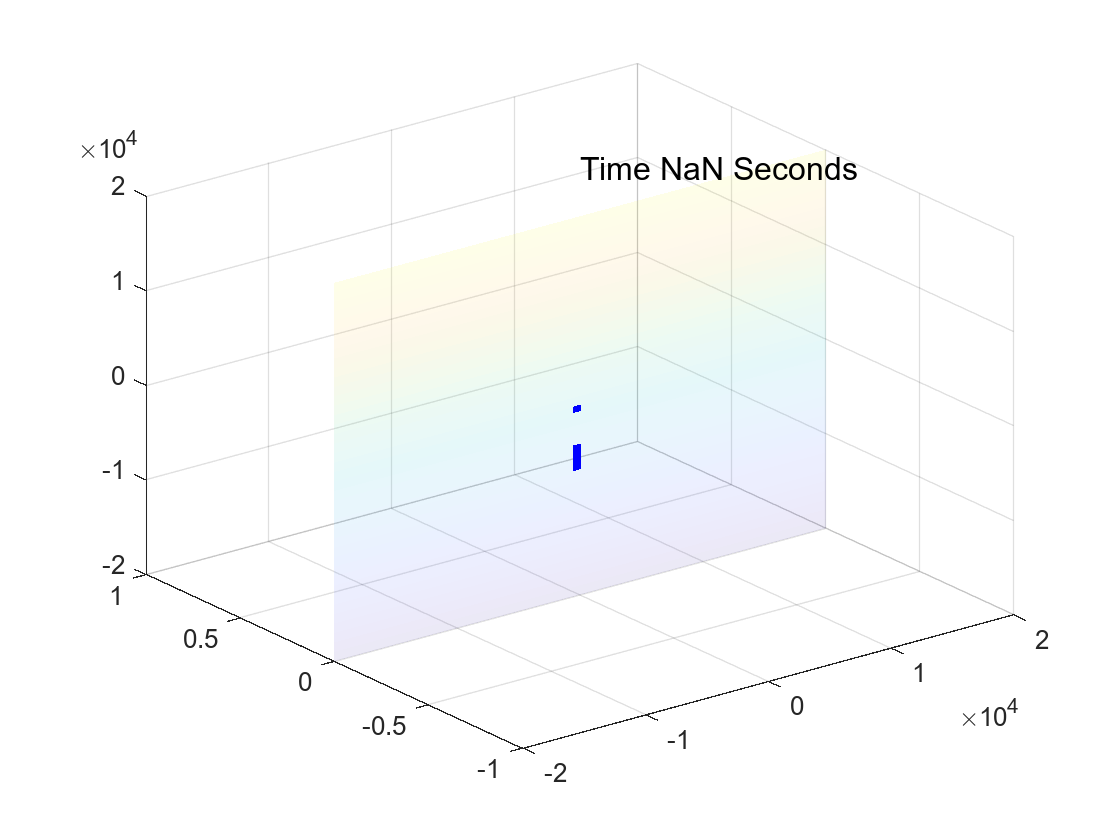

%Lawnguy

% Clear the previous format and info and claculations 
clc; clear;
format short; format compact;

% Create a datastore for the CSV file
ds = datastore('TimeStamps.csv', 'ReadVariableNames', false);  % Set false if there's no header row
ds.VariableNames = {'time_stamp', 'x_cord', 'z_cord'};  % Manually define variable names
ds.SelectedVariableNames = {'time_stamp', 'x_cord', 'z_cord'};

% Process the CSV data in chunks
while hasdata(ds)
    dataChunk = read(ds); % Read the next chunk of data

    % Get the a,b,c,d cols and set vars to the data
    time_stamp = str2double(dataChunk{:,1});  % Convert time_stamp to numeric
    x_cord = dataChunk{:,2};
    z_cord = dataChunk{:,3};

    % Define the grid for surface plot
    [xGrid, zGrid] = meshgrid(-20000:1000:20000, -20000:1000:20000);
    yGrid = zeros(size(xGrid));

    % Create the 3D graph
    figure; 
    hold on; 
    grid on; 
    view(3);

    surf(xGrid, yGrid, zGrid, 'FaceAlpha', 0.1, 'EdgeColor', 'none');

    colors = {'r', 'g', 'b', 'm'};

    % Loop through the data chunk
    for i = 1:length(time_stamp)
        x = x_cord(i);
        z = z_cord(i);
        y = 0; 

        % Assign colors based on coordinates
        if x >= 0 && z >= 0 
            color = colors{1};
        elseif x < 0 && z >= 0
            color = colors{2};
        elseif x < 0 && z < 0 
            color = colors{3};
        else
            color = colors{4};
        end

        % Define vertices for the square in 3D space
        squareX = [x, x+16, x+16, x];
        squareY = [y, y, y, y];
        squareZ = [z, z, z+16, z+16];

        % Use patch to draw the square with transparency
        patch(squareX, squareY, squareZ, color, 'FaceAlpha', 0.5, 'EdgeColor', color);

        % Display the timestamp as text (convert to string properly)
        text(0, 0, 25000, ['Time ', num2str(time_stamp(i)), ' Seconds'], 'FontSize', 12, 'Color', 'k');

        pause(0.001);  % Simulate real-time plotting
        delete(findobj('String', ['Time ', num2str(time_stamp(i)), ' Seconds']));
    end

    xlabel('X Cords');
    ylabel('Y Cords');
    zlabel('Z Cords');
    title('3D Minecraft Real Time WDL');

    hold off;
end

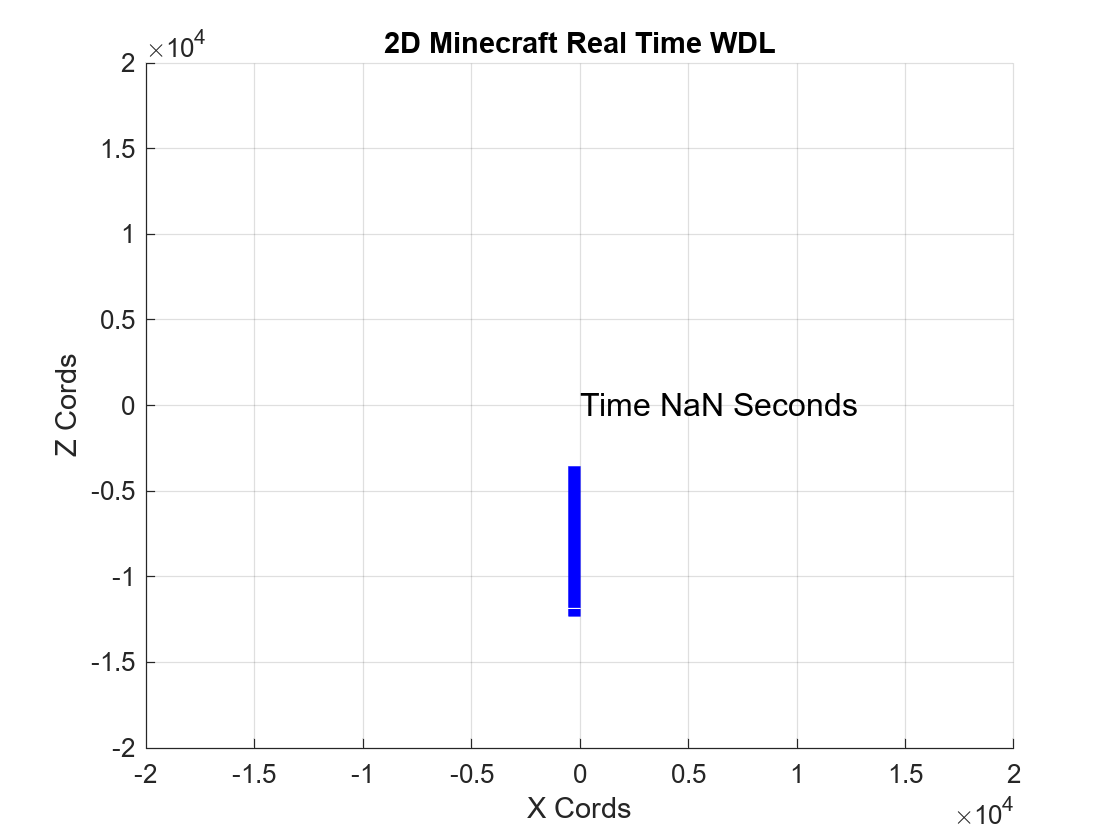

%Lawnguy 2D version

% Clear the previous format and info and calculations 
clc; clear;
format short; format compact;

% Create a datastore for the CSV file
ds = datastore('TimeStamps.csv', 'ReadVariableNames', false);  % Set false if there's no header row
ds.VariableNames = {'time_stamp', 'x_cord', 'z_cord'};  % Manually define variable names
ds.SelectedVariableNames = {'time_stamp', 'x_cord', 'z_cord'};

% Create the figure for the 2D plot
figure;
hold on;
grid on;

colors = {'r', 'g', 'b', 'm'};  % Color options

% Define an empty array for storing patch handles
patchHandles = [];  % Preallocate an empty array for patch handles
textHandle = text(0, 0, 'Time: 0 Seconds', 'FontSize', 12, 'Color', 'k');  % Preallocate the text object

xlim([-20000 20000]);  % Set limits for the X axis
ylim([-20000 20000]);  % Set limits for the Z axis
xlabel('X Cords');
ylabel('Z Cords');
title('2D Minecraft Real Time WDL');

% Process the CSV data in chunks
while hasdata(ds)
    dataChunk = read(ds);  % Read the next chunk of data

    % Get the time, x, and z coordinates from the data chunk
    time_stamp = str2double(dataChunk{:,1});  % Convert time_stamp to numeric
    x_cord = dataChunk{:,2};
    z_cord = dataChunk{:,3};

    % Loop through the data chunk
    for i = 1:length(time_stamp)
        x = x_cord(i);
        z = z_cord(i);

        % Assign colors based on coordinates
        if x >= 0 && z >= 0
            color = colors{1};  % Red for top-right quadrant
        elseif x < 0 && z >= 0
            color = colors{2};  % Green for top-left quadrant
        elseif x < 0 && z < 0
            color = colors{3};  % Blue for bottom-left quadrant
        else
            color = colors{4};  % Magenta for bottom-right quadrant
        end

        % Define vertices for the square in 2D space
        squareX = [x, x+16, x+16, x];
        squareZ = [z, z, z+16, z+16];

        % Check if a patch already exists for this index
        if i > length(patchHandles) || isempty(patchHandles{i})
            % Create a new patch object if it doesn't exist
            patchHandles{i} = patch(squareX, squareZ, color, 'FaceAlpha', 0.5, 'EdgeColor', color);
        else
            % Update existing patch vertices and color
            set(patchHandles{i}, 'XData', squareX, 'YData', squareZ, 'FaceColor', color);
        end

        % Update the text display for time
        set(textHandle, 'String', ['Time ', num2str(time_stamp(i)), ' Seconds']);
    end

    drawnow;  % Update plot without blocking
end


hold off;


